# Quiz 6

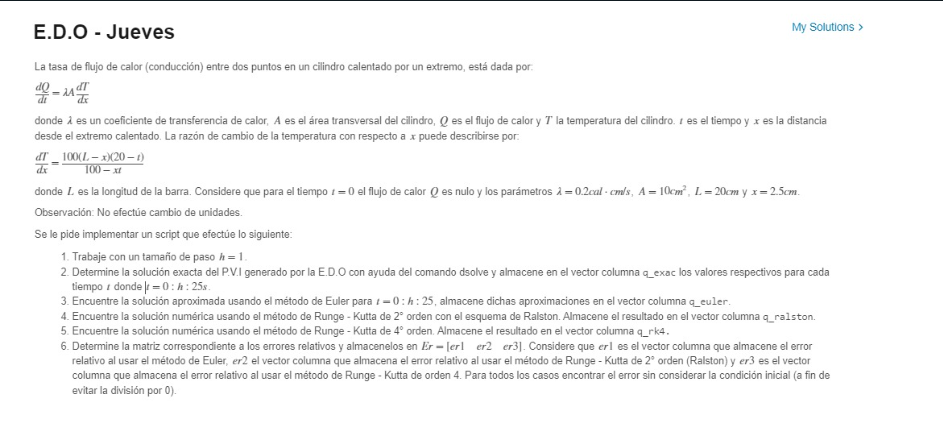

format long
%variables q_exac, q_euler , q_ralston, q_rk4, Er
syms t Q(t)
gamma = 0.2; A =10; L =20;x=2.5; h=1;y0=0;
%T = 100*(L-x)*(20-t)/100-x*t
%Q = gamma*A*T


%1er item
y_sol = dsolve(diff(Q(t),t) == gamma*A*100*((L-x)*(20-t))/(100-x*t),Q(0)==0);
y_sol = matlabFunction(y_sol)

y_sol = function_handle with value:
    @(t)t.*1.4e+3-pi.*2.8e+4i+log(t-4.0e+1).*2.8e+4-log(4.0e+1).*2.8e+4




% Hallando valor exacto
r = 0:h:25;
q_exac = y_sol(r)'

q_exac = 1.0e+03 *

                   0
   0.691101376439881
   1.363787757148573
   2.017076838848065
   2.649905561580861
   3.261121006513364
   3.849469974062304
   4.413587005871232
   4.951980563202116
   5.463017010393872




% 2do item
f = @(t,Q) gamma*A*100*((L-x)*(20-t))/(100-x*t);
q_euler = euler(f,0,25,y0,h)

q_euler = 1.0e+03 *

                   0
   0.700000000000000
   1.382051282051282
   2.045209176788124
   2.688452420031368
   3.310674642253590
   3.910674642253590
   4.487145230488885
   5.038660382004037
   5.563660382004036


er1 = abs(q_exac - q_euler)/abs(q_exac);


% 3er item
a = Heun(f, 0, 25, y0, h);
q_ralston = a(:,2)

q_ralston = 1.0e+03 *

                   0
   0.691025641025641
   1.363630229419703
   2.016830798409746
   2.649563531142479
   3.260674642253590
   3.848909936371236
   4.412902806246460
   4.951160382004035
   5.462047478778229


er2 = abs(q_exac - q_ralston)/abs(q_exac);

%4to item
b = rk4(f, 0, 25, y0, h);
q_rk4 = b(:,2)

q_rk4 = 1.0e+03 *

                   0
   0.691101374012766
   1.363787751962302
   2.017076830514539
   2.649905549644628
   3.261120990437534
   3.849469953211049
   4.413586979487865
   4.951980530381416
   5.463016970046888


er3 = abs(q_exac - q_rk4)/abs(q_exac);

%5to item
Er = [er1 er2 er3]

Er =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0               

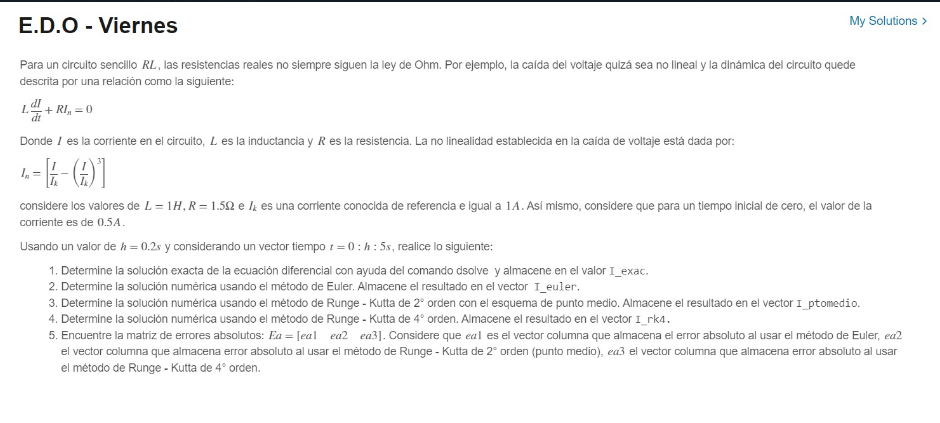

format long
R = 1.5;
L = 1;

f = @(i,t)( (-1*R/L)*(i - i^3));

h = 0.2;
a = 0;
b = 5;
i0 = 0.5;

syms i(t) t
i(t) = dsolve(diff(i,t) == (-1*R/L)*(i - i^3) , i(0) == i0 )

$$i(t) = \sqrt{\frac{1}{{\mathrm{e}}^{3\,t+\log\left(3\right)}+1}}$$


i = matlabFunction(i(t))

i = function_handle with value:
    @(t)sqrt(1.0./(exp(t.*3.0+log(3.0))+1.0))



tt = (a:h:b)';

I_exac = i(tt)

I_exac =    0.500000000000000
   0.393251312874718
   0.302056213140026
   0.228521782880838
   0.171323498493417
   0.127768418103826
   0.095003695831437
   0.070524212983050
   0.052304341968762
   0.038771945742969



[z1] = EULER(f,a,b,i0,h);

[z2] = RK2(f,a,b,i0,h);

[z3] = RK4(f,a,b,i0,h);


I_euler = z1(:,1:2)

I_euler = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.005000000000000
   0.004000000000000   0.004424000000000
   0.006000000000000   0.003416000000000
   0.008000000000000   0.002264000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.001400000000000
   0.014000000000000   0.002984000000000
   0.016000000000000   0.007016000000000
   0.018000000000000   0.014504000000000


I_ptomedio = z2(:,1:2)

I_ptomedio = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.004712000000000
   0.004000000000000   0.003920000000000
   0.006000000000000   0.002840000000000
   0.008000000000000   0.001832000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.002192000000000
   0.014000000000000   0.005000000000000
   0.016000000000000   0.010760000000000
   0.018000000000000   0.020552000000000


I_rk4 = z3(:,1:2)

I_rk4 = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.004706000000000
   0.004000000000000   0.003896000000000
   0.006000000000000   0.002786000000000
   0.008000000000000   0.001736000000000
   0.010000000000000   0.001250000000000
   0.012000000000000   0.001976000000000
   0.014000000000000   0.004706000000000
   0.016000000000000   0.010376000000000
   0.018000000000000   0.020066000000000



ea1 = abs(I_exac - I_euler)./abs(I_exac);

ea2 = abs(I_exac - I_ptomedio)./abs(I_exac);

ea3 = abs(I_exac - I_rk4)./abs(I_exac);

Ea = [ea1 ea2 ea3]

Ea = 1.0e+05 *

   0.000010000000000                   0   0.000010000000000                   0   0.000010000000000                   0
   0.000004914193711   0.000002714515721   0.000004914193711   0.000001982159616   0.000004914193711   0.000001966902197
   0.000003242568191   0.000004646280419   0.000003242568191   0.000002977716827   0.000003242568191   0.000002898261418
   0.000016255702736   0.000004948246758   0.000016255702736   0.000002427699295   0.000016255702736   0.000002191397970
   0.000036695287397   0.000003214766333   0.000036695287397   0.000000693220814   0.000036695287397   0.000000132877365
   0.000068266602564   0.000000957324359   0.000068266602564   0.000000957324359   0.000068266602564   0.000000216674679
   0.000116310875540   0.000004736268813   0.000116310875540   0.000013072786599   0.000116310875540   0.000010799190839
   0.000188513381544   0.000032311709323   0.000188513381544   0.000060897636266   0.000188513381544   0.000056728855253
   0.00029590194


% Plot
tt = a:0.01:b;
I_exac = i(tt)

I_exac =    0.500000000000000   0.494385769444593   0.488793955544283   0.483225846477526   0.477682691948912   0.472165702625893   0.466676049667819   0.461214864344972   0.455783237745096   0.450382220564682   0.445012822982099   0.439676014609508   0.434372724520347   0.429103841349067   0.423870213459723   0.418672649179920   0.413511917096599   0.408388746410107   0.403303827342964   0.398257811599772   0.393251312874718   0.388284907403146   0.383359134553745   0.378474497457945   0.373631463673178   0.368830465876760   0.364071902587222   0.359356138910018   0.354683507304658   0.350054308370387   0.345468811647683   0.340927256432932   0.336429852603782   0.331976781452772   0.327568196526981   0.323204224471538   0.318884965874988   0.314610496114585   0.310380866199755   0.306196103612048   0.302056213140026   0.297961177707667   0.293910959194948   0.289905499249377   0.285944720087385   0.282028525284534   0.278156800553639   0.274329414509973   0.270546219422805   0.266807

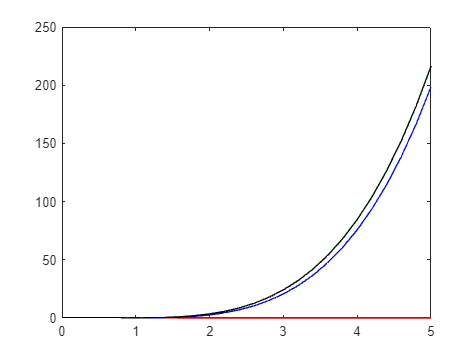


plot(tt, I_exac,'r', I_euler(:,1), I_euler(:,2),'b', I_ptomedio(:,1), I_ptomedio(:,2),'g', I_rk4(:,1), I_rk4(:,2), 'black')

## Quiz 6

format long
%variables I_exac  I_euler   I_ptomedio  I_rk4  Ea 
%I_exac (vector columna)
%I_euler (vector columna)
%I_ptomedio (vector columna)
%I_rk4 (vector columna)
%Ea (matriz)

R = 1.5; L = 1;
a = 0; b = 5; h = 0.2; I_0 = 0.5;
ts = (a:h:b)'

ts =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000
   1.200000000000000
   1.400000000000000
   1.600000000000000
   1.800000000000000



f = @(I,t)((-R/L)*(I - I^3))

f = function_handle with value:
    @(I,t)((-R/L)*(I-I^3))



% item 1
syms I(t) t
I(t) = dsolve(diff(I,t) == (-R/L)*(I - I^3), I(0) == I_0)

$$I(t) = \sqrt{\frac{1}{{\mathrm{e}}^{3\,t+\log\left(3\right)}+1}}$$

I = matlabFunction(I(t))

I = function_handle with value:
    @(t)sqrt(1.0./(exp(t.*3.0+log(3.0))+1.0))



I_exac = I(ts)

I_exac =    0.500000000000000
   0.393251312874718
   0.302056213140026
   0.228521782880838
   0.171323498493417
   0.127768418103826
   0.095003695831437
   0.070524212983050
   0.052304341968762
   0.038771945742969



% item 2z
z = EULER(f,a,b,I_0,h);

I_euler = z(:,1:2)

I_euler = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.005000000000000
   0.004000000000000   0.004424000000000
   0.006000000000000   0.003416000000000
   0.008000000000000   0.002264000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.001400000000000
   0.014000000000000   0.002984000000000
   0.016000000000000   0.007016000000000
   0.018000000000000   0.014504000000000



% item 3
z = RK2(f,a,b,I_0,h);

I_ptomedio = z(:,1:2)

I_ptomedio = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.004712000000000
   0.004000000000000   0.003920000000000
   0.006000000000000   0.002840000000000
   0.008000000000000   0.001832000000000
   0.010000000000000   0.001400000000000
   0.012000000000000   0.002192000000000
   0.014000000000000   0.005000000000000
   0.016000000000000   0.010760000000000
   0.018000000000000   0.020552000000000



% item 4
z = RK4(f,a,b,I_0,h);

I_rk4 = z(:,1:2)

I_rk4 = 1.0e+02 *

                   0   0.005000000000000
   0.002000000000000   0.004706000000000
   0.004000000000000   0.003896000000000
   0.006000000000000   0.002786000000000
   0.008000000000000   0.001736000000000
   0.010000000000000   0.001250000000000
   0.012000000000000   0.001976000000000
   0.014000000000000   0.004706000000000
   0.016000000000000   0.010376000000000
   0.018000000000000   0.020066000000000




% item 5
ea1 = abs(I_exac - I_euler);

Arrays have incompatible sizes for this operation.

Related documentation


ea2 = abs(I_exac - I_ptomedio);

ea3 = abs(I_exac - I_rk4);

Ea = [ea1 ea2 ea3]

tt = a:0.01:b;

I_exac = I_exac(tt)

plot(tt, I_exac,'r', I_euler(:,1), I_euler(:,2),'b', I_ptomedio(:,1), I_ptomedio(:,2),'g', I_rk4(:,1), I_rk4(:,2), 'black')

function z = EULER(f,a,b,y0,h)
    t = (a:h:b)';
    z = [];

    for i = 1:length(t)-1
        k1 = f(t(i),y0);
        y1 = y0 + k1*h;
        z = [z;t(i) y0 k1 y1];
        y0 = y1;
    end
end


function z = RK2(f,a,b,y0,h)
    t = (a:h:b)';
    z = [];

    for i = 1:length(t)-1
        k1 = f(t(i),y0);
        k2 = f(t(i)+h,y0+k1*h);
        y1 = y0 + (k1/2 + k2/2)*h;
        z = [z;t(i) y0 k1 k2 y1];
        y0 = y1;    
    end
end

function z = RK4(f,a,b,y0,h)
    t = (a:h:b)';
    z = [];
    
    for i = 1:length(t)-1
        k1 = f(t(i),y0);
        k2 = f(t(i)+h/2,y0 + k1*(h/2));
        k3 = f(t(i)+h/2,y0 + k2*(h/2));
        k4 = f(t(i) + h , y0 + k3*h);
        y1 = y0 + (k1 + 2*k2 + 2*k3 +k4)*(h/6);
        z = [z;t(i) y0 k1 k2 k3 k4 y1];
        y0 = y1;    
    end
end